# Debugging and Handling Errors

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

Everyone makes mistakes when coding or interacting with computer programs, but you can identify and correct mistakes. An integrated development environment (IDE) is a software application that offers many capabilities a programmer might like, such as editing, debugging, version control, testing, etc., in one program. 

This script will introduce you to some of the debugging tools available in MATLAB. 

## Syntax Highlighting & Automatic Suggestions

Before you ever get to the point of worrying about errors, modern editing tools for code incorporate [syntax highlighting](https://www.mathworks.com/help/matlab/matlab_env/check-syntax-as-you-type.html) and code suggestions or autocompletion, such as adding a ) after the cursor when an ( is typed in a syntactically correct spot.

note = "MATLAB identifies strings";

  **Try**. Test the automatic suggestions using `plot`:

- On the line following the definition of the variable `x`, type `plot( `and then pause. What suggestion is made? You can use the **Tab** key to accept the suggestion. This is called tab completion.

- Say you don't want to use the first suggestion, and you start in with a different usage of `plot` by typing `plot(x,cos(x)` and then pause. What suggestions are made? 

- Continue on by typing `plot(x,cos(x),":","` and scroll through the options suggested. Full details are in the documentation, but if you half-remember that something is possible, you may be able to guess and check your way through using automated suggestions. Alternately, you can access the list of suggestions by clicking on the hyperlink `options` in the pop-up suggestion box.

x = 1:10;


 Remember that automated suggestions are only suggestions. Especially in instances where more than one version of a function exists, the initial suggestion may not be what you are trying to do. If you have any doubt, check the documentation.

  **Try**. 

- Observe the options shift if you start by typing `table(` and then continue with `table("S`

- Read the documentation for `table`; do you see a reason this might be happening?

## Static Errors

Before you ever run your code, analysis [can detect some errors statically](https://www.mathworks.com/help/matlab/matlab_prog/check-code-for-errors-and-warnings.html). Many of these will fall into the category of syntax errors, where you have written code that doesn't fit the grammar of the programming language. In MATLAB, this could be something like

  **Try**. Paste one or more of the example errors above into a code box. You should see an orange squiggle underlining a character related to the problem in the code box and an error symbol   on the top-right edge of the Live Editor with a red line appearing below it for each error. If you hover over either the red line or the underlined character, the related error will pop up. Use these messages to fix the code, so there are no errors. 

### Warnings

The automated checking will warn you about possibly incorrect code or suggest improving the code. Like errors, warnings are also identified within a code box by orange squiggles underlining a character, but in this case, the line on the right edge of the Live Editor will be orange. If you run code containing warnings, you will have a warning symbol   appear on the top-right edge of the Live Editor window. Clicking on the warning icon will step through each warning in the code. 

  **Try**. Highlight the example code that generates warnings, below, and convert it to active code using the  **Code** button on the toolstrip, which you can find on both the Live Editor and Insert tabs. Observe the warnings, then run the code. Can you resolve the warnings by editing the code?

  **Pro-tip**. You may find that there are warnings about code that you have written that way on purpose. If that is the case, you can choose to judiciously [suppress warnings](https://www.mathworks.com/help/matlab/matlab_prog/check-code-for-errors-and-warnings.html#brqxeeu-167). 

## Run-time Errors

Some errors in a program may not become apparent until the program is executed. For instance, you might call on a function that is not on your MATLAB path, try to access the value of a variable that is not scoped in the current workspace, or try to compare variables of different sizes. These run-time errors will generate fatal errors: your program will not run past the point of the error until you resolve them. 

  **Try**. Paste the example code that generates run-time errors, above, into a code box. Observe the lack of errors or warnings related to this code. Then run this section. An error icon,  , will appear in the top left corner of the Live Editor pane as well as on the right end of the line of code that generated the error. Then change `B` so it has the same dimensions as `A`, and rerun the code. 

### Silent bugs

Other errors are more insidious. Perhaps you unintentionally overloaded a function or a variable and later try to access both versions at different points in your code. Perhaps you are not checking user input, and your code does not handle the values provided. Perhaps you have an error in your logic or mathematics that results in incorrect answers. 

Locating silent bugs like these requires testing the code you have written against the expected output, usually in very simple cases or small steps that you can compute by hand. While large projects are likely to involve dedicated people thinking about how to test the code, all programmers need to think about how to organize and document their code to facilitate finding bugs.

Methods to try when working to locate a silent bug:

- You can stop suppressing output, especially on lines that you suspect might be causing problems. Alternately, you can use your mouse to hover over variables to check their values, even when the value is suppressed.

- Comment out parts of the code, or replace complicated sections temporarily with simpler versions such as a hard-coded value rather than a dynamically computed value.

- Add section breaks and check the output in smaller pieces. Are you still seeing what you expect? 

** Exercise 1**. Find and fix the silent bug in the following code. 

% Define two row vectors
v1 = sum(randi(5,5));
v2 = randi(10,[5,1]);

% Add the values to create a new total vector
tot = v1+v2;

% Plot the vector and observe its shape
plot(tot)

 **Reflect**.

- How did you identify the bug in this code? Is there something the author of the code did that helped you find the error? Or something that the IDE did to help you find the error?  

### Breakpoints and Code Stepping

As your code gets more involved, you will find that locating and eliminating bugs becomes more of a challenge. A variety of tools are available to help you isolate bugs.

Observe the line numbers in the margin of the frame to the left of the code box. If you hover your mouse over the line number of an executable line of code, a light red box will indicate the current line number. If you click the line number, a solid red box will appear, indicating that you have set a breakpoint on that line. 

  **Try**. 

In the code that creates `newBoard`, try the following:

- Set a breakpoint on the line that says

It should look like this:

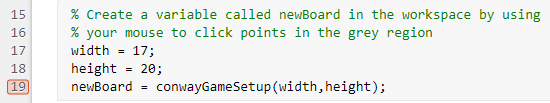

          2. Then run this section of code. You should observe that execution of the code stops after setting the `height` and before running `conwayGameSetup`. A green arrow shows where the execution will go next. There is also a downward-curving green arrow showing that `conwayGameSetup` is a function that you can step into if you choose. You should also observe that the Command Window changes from a command prompt of `>>` to a command prompt of `K>` to remind you that you are inside the MATLAB debugger. 

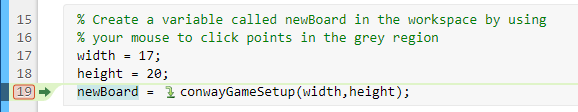

The **Live Editor** tab in the toolstrip also offers different options in the **Run** section when paused at a breakpoint:

 **Continue** will continue the execution to the next breakpoint or the end of the code.

 **Step** will execute exactly one line and move the "stopped here" arrow forward one line.

 **Step in** will step into (and open) the function being called.

 **Step out** will finish the execution of the function and step out, returning to the line where the function was called. It will not move forward to the next line of code.

  **Stop** ends the attempt to execute the code, allowing you to apply changes you want to make and then try running the code again.

          3. Use the  **Step in** tool to enter the `conwayGameSetup` function

          4. Add a new breakpoint on line 12, 

of `conwayGameSetup`. Observe that the workspace currently contains only `width` and `height` because you are now inside a local function with its local variables. 

          5. Use the  **Continue** button to execute Lines 1-11 of `conwayGameSetup`. This adds two variables to the workspace. 

          6. Return to the `debugging.mlx` script and observe that no plot has opened yet. Then use the  **Step** button, which will return your focus to the `conwayGameSetup` function, and use the tabs in the Live Editor pane to return to `debugging.mlx`. Observe that now the plot has been created. 

          7. Use either  **Continue**,   **Step out**, or repeated use of  **Step** to finish the execution of this section of code. 

% Create a variable called newBoard in the workspace by using
% your mouse to click points in the grey region
width = 17;
height = 20;
newBoard = conwayGameSetup(width,height);

  **Try**. 

- After setting up a starting configuration of 'live' cells in the previous section, run this section to observe how Conway's Game of Life evolves new patterns over time. 

- Use the debugging tools to stop after the 4th iteration and modify the current board state by changing the life status of at least two cells, then continue running the simulation. Did it change the results? 

maxIterations = 30;
edgePadding = 3;
runConwayGame(width,height,edgePadding,newBoard,maxIterations)

## To Learn More

The [MATLAB Programming Techniques](https://matlabacademy.mathworks.com/details/matlab-programming-techniques/mlpr) course available as a self-paced course in the Online Training Suite includes three chapters on programming defensively, verifying behavior, and debugging your code. 

## Interpreted Languages versus Compiled Languages

There are many ways to describe programming languages, but one classification is between interpreted and compiled languages. As an interpreted language, MATLAB evaluates and displays the results of each computation before continuing to the next. If you do not want to display this result, you can suppress the output of that line by terminating the line with a semicolon, but that line of code is still run before execution continues. Other interpreted languages include Python and JavaScript. Compiled languages include C, Java, and Fortran, where an entire program must be compiled into a machine-readable unit before it can be run. In compiled languages, a program can fail to compile.

## Further Exploration: Writing Bug Reports

Writing coherent, concise, and reproducible bug reports is a positive contribution to any (programming) community. If you find a programming mistake in someone else's work, it is important to let them know. You should include all the information you can acquire that may be relevant, including error messages, language version, the operating system you are working on, log files, etc.  Including a minimal testcase that can direct the programmer as tightly as possible to the problem you identified is also helpful. Then you must include steps to reproduce, if at all possible. It is challenging to diagnose or fix a bug without the ability to reproduce an error.

[⇦ Main Menu](matlab:open('MainMenu.mlx'))